a?

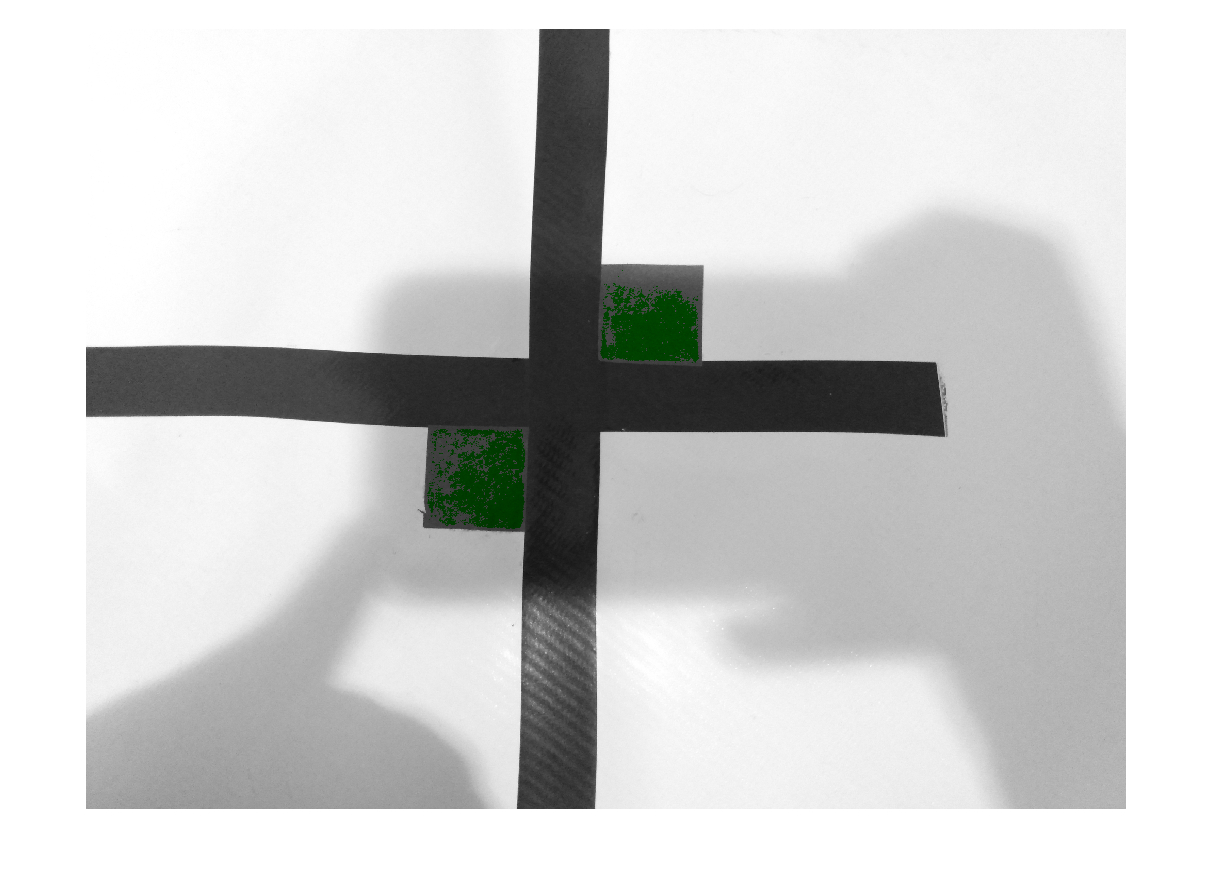

clear all
cruce=imread("imagen.jpg");
imagenGris=rgb2gray(cruce);
imR = double(cruce(:,:,1));
imG = double(cruce(:,:,2));
imB = double(cruce(:,:,3));
imagenV = (imG-imB-imR);
imagen_binaria = imagenV > 0;
imagen_binaria_filtrada = medfilt2(imagen_binaria);

mascara = 1-imagen_binaria_filtrada;

imagen_verde = double(imagenGris)/255;
imagen_azul = double(imagenGris) .*mascara/255;
imagen_roja = double(imagenGris) .*mascara/255;

imagen_final = cat(3,imagen_roja,imagen_verde,imagen_azul);

figure
imshow(imagen_final)